# Lab - Root Finding 2 - Open methods

**Topics: **Newton Raphson 

clear, clc, format compact

## Find roots using Newton-Raphson

### Set up problem

Determine the highest real root of $f\left(x\right)=x^3 -6x^2 +11x-6\ldotp 1$

f = @(x) x.^3 - 6*x.^2 + 11*x - 6.1;
df = @(x) 3*x.^2 - 12*x + 11

df = function_handle with value:
    @(x)3*x.^2-12*x+11

format long
MPRAE = @(curr, prev) abs((curr-prev)/curr)*100;


### Plot to see what is reasonable

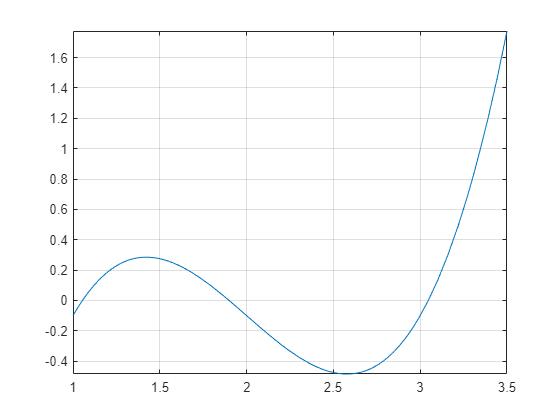

fplot(f, [1,3.5])
grid on

### Guess #1: Three iterations with initial guess lower than target root


$$x_{i+1} =x_i -\frac{f\left(x_i \right)}{f^{\prime } \left(x_i \right)}$$


x0 = 2;
x1 = x0-f(x0)/df(x0)

x1 =    1.900000000000000

ea1 = MPRAE(x1,x0)

ea1 =    5.263157894736822

x2 = x1- f(x1)/df(x1)

x2 =    1.898969072164951

ea2 = MPRAE(x2,x1)

ea2 =    0.054288816503671


x3 = x2 - f(x2)/df(x2)

x3 =    1.898968742119025

ea3 = MPRAE(x3,x2)

ea3 =      1.738027168474629e-05

### Check root estimates - guess #1

f(x3)

ans =     -3.552713678800501e-14

### Guess #2: Loop until root error is < 0.001% with initial guess above the target root


$$x_{i+1} =x_i -\frac{f\left(x_i \right)}{f^{\prime } \left(x_i \right)}$$


ea = 100;
x = [4];
n = 1;

while  ea > .001
    x(n+1) = x(n) - f(x(n))/df(x(n));
    n = n + 1;
    ea = MPRAE(x(end),x(end-1));
end
x'

ans =    4.000000000000000
   3.463636363636364
   3.173991994938342
   3.064232506126427
   3.047088482441657
   3.046680760145118
   3.046680531804677


f(x')

ans =    5.900000000000000
   1.571811419984977
   0.344070929734267
   0.041107468209896
   0.000933350897030
   0.000000522128241
   0.000000000000172


### Check root estimates - guess #2

f(x(end))

ans =      1.723066134218243e-13